# Initialization

clear all;
data = load("sub-x32541_task-conflict.emg.mat");
struct = data.x32541_conflict000_wave_data;

x_units = struct.xunits;
start_t = struct.start;
delta_t = struct.interval;
sampling = 1 / delta_t;
points = double(struct.points);
frames = struct.frameinfo;
channels = struct.chaninfo;
values = struct.values;
t = linspace(start_t, delta_t*double(points), points);

clear("data");
clear("struct");

data = load("32541_1_2022_Jun_17_1139_V_cued_r_time.mat");
trial_type = data.triallist;
press_time = data.presstime;
pressed = data.pressname;
clear('data');

% BPF -> filtering data and rectifying
cutoff_low = 40; % motoneurons fire at 14 +- 4 hz, but I want to filter out movement remaints
cutoff_high = 400; % too fast for a motorneuron
filter_order = ceil( (sampling / (cutoff_high - cutoff_low)) * (20 / 22)); % Fred Harris rule

[b, a] = butter(filter_order, [cutoff_low/(sampling/2), cutoff_high/(sampling/2)], 'bandpass');

filtered_signal = filtfilt(b, a , values);

% Removing DC offset by removing the avg
filtered_signal = filtered_signal - mean(filtered_signal);

% Signal rectification
rectified_signal = abs(filtered_signal);
threshold_baseline = 0.2; % arbitrary threshold

sd = std(rectified_signal);

% Enveloping signal
cutoff = 10; 
filter_order = ceil( (sampling / (cutoff_high - cutoff_low)) * (20 / 22));

[b, a] = butter(filter_order, cutoff/(sampling/2), 'low');
enveloped_signal = filtfilt(b, a , rectified_signal); % display purposes

% Power spectrum
ps = fft(values);
ps_f = fft(rectified_signal);
f = (0:points-1)*(sampling/points);
power = abs(ps).^2 ./ points;
power_f = abs(ps_f).^2 / points;

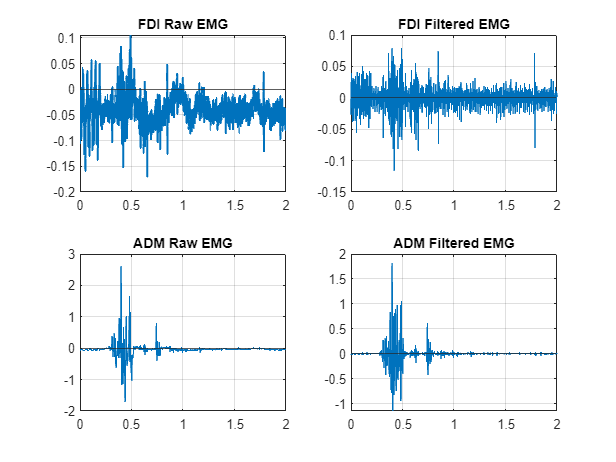

% Plotting
figure()

subplot(2,2,1)
xlabel(x_units)
ylabel(channels(1).units)
plot(t,values(:,1,2), 'LineWidth', 1.5)
yline(0)
title(channels(1).title + " Raw EMG")
grid("on")

subplot(2,2,3)
xlabel(x_units)
ylabel(channels(2).units)
plot(t,values(:,2,2))
yline(0)
title(channels(2).title + " Raw EMG")
grid("on")

subplot(2,2,2)
xlabel(x_units)
ylabel(channels(1).units)
plot(t,filtered_signal(:,1,2))
yline(0)
title(channels(1).title + " Filtered EMG")
grid("on")

subplot(2,2,4)
xlabel(x_units)
ylabel(channels(2).units)
plot(t,filtered_signal(:,2,2))
yline(0)
title(channels(2).title + " Filtered EMG")
grid("on")

% calculating onset and finish times | FDI | ADM | BOX |
onset_t = -1 * ones([length(values(1,1,:)), 3]); % if column 1 != -1 -> FDI else ADM. if both FDI and ADM -> value in both
end_signal_t = -1 * ones([length(values(1,1,:)), 2]);

for j = 1:length(frames) % for all tests
    if press_time(j) ~= 99
        onset_t(j,3) = interp1(t,t, press_time(j), 'nearest');
    else
        onset_t(j,3) = -1;
    end
    
    % check the biggest ps
    if mean(power_f(1:0.5*points,1,j)) > mean(power_f(1:0.5*points,2,j)) % only check first half bc it's mirrored
        check_ps = 1;
    else 
        check_ps = 2;
    end

    for i = 1:length(values(1,1:2,j)) % channels 3 to 6 are noise
        if i == check_ps
            onsets_i = find(enveloped_signal(:,i,j) >  2 * sd(:,i,j));% & rectified_signal(:,i,j) > threshold_baseline); 
        else
            onsets_i = [];
        end
        
        if ~isempty(onsets_i)
            onsets_t = t(onsets_i);
            onset_t(j,i) = onsets_t(1);
            end_signal_t(j,i) = onsets_t(end);
        else % -1 to indexes where there is no movement
            onset_t(j,i) = -1;
            end_signal_t(j,i) = -1;
        end
    end
end

if ismember([-1 -1],onset_t(:,1:2),'rows')
    disp("Didn't find onset somewhere")
else
    disp("Ok")
end

Ok


% Checking which trial is FDI and which is ADM
trial_type;

detected = []; % 1 = FDI; 2 = ADM; 3 = both
t1_index = [];
t2_index = [];
t3_index = [];
t4_index = [];

low_threshold = 0.1; % filter now
skipped = 0;
for i = 1:length(frames)
    if any(onset_t(i,1:2) > low_threshold)
        switch trial_type(i)
            case 1
                t1_index = [t1_index, i - skipped];
            case 2
                t2_index = [t2_index, i - skipped];
            case 3
                t3_index = [t3_index, i - skipped];
            case 4
                t4_index = [t4_index, i - skipped];
        end

        if onset_t(i,2) == -1 && onset_t(i,1) ~= -1
            temp = 1;
        end
        if onset_t(i,1) == -1 && onset_t(i,2) ~= -1
            temp = 2;
        end
        if onset_t(i,2) ~= -1 && onset_t(i,1) ~= -1
            temp = 3;
        end
    
        detected = [detected, temp];
    else
        skipped = skipped + 1
    end
end

skipped = 1

skipped = 2


% for i = 1:length(t1_index)
%     disp("Test number: " + t1_index(i) + " Detected movement type: " + detected(t1_index(i)))
% end
disp("Test number: " + t1_index(1) + " Detected movement type: " + detected(t1_index(1)))

Test number: 1 Detected movement type: 2


% for i = 1:length(t2_index)
%     disp("Test number: " + t2_index(i) + " Detected movement type: " + detected(t2_index(i)))
% end
disp("Test number: " + t2_index(1) + " Detected movement type: " + detected(t2_index(1)))

Test number: 8 Detected movement type: 1


% for i = 1:length(t3_index)
%     disp("Test number: " + t3_index(i) + " Detected movement type: " + detected(t3_index(i)))
% end
disp("Test number: " + t3_index(1) + " Detected movement type: " + detected(t3_index(1)))

Test number: 2 Detected movement type: 1


% for i = 1:length(t4_index)
%     disp("Test number: " + t4_index(i) + " Detected movement type: " + detected(t4_index(i)))
% end
disp("Test number: " + t4_index(1) + " Detected movement type: " + detected(t4_index(1)))

Test number: 6 Detected movement type: 2


indexes = find(onset_t(:,3) == -1);

for i = 1:length(indexes)
    disp("Test number: " + indexes(i) + " | Detected response: " + detected(indexes(i)))
end

Test number: 9 | Detected response: 2
Test number: 27 | Detected response: 2
Test number: 32 | Detected response: 1


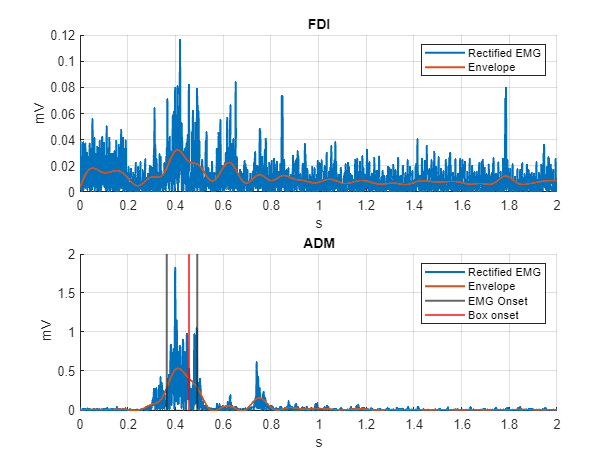

% type 1
figure()

for i = 1:length(values(1,1:2,2)) % 6 channels: 3 to 6 are noise
    subplot(length(rectified_signal(1,1:2,1)),1,i)
    hold on
    plot(t, rectified_signal(:,i,2), t, enveloped_signal(:,i,2), 'LineWidth', 1.5)
    if onset_t(2,i) ~= -1
        xline(onset_t(2,i),'LineWidth',1.5)
        xline(end_signal_t(2,i),'LineWidth',1.5)
        if onset_t(2,3) ~= -1
            xline(onset_t(2,3),'LineWidth',1.5,'Color','r')
            legend('Rectified EMG', 'Envelope', 'EMG Onset', '', 'Box onset')
        else
            legend('Rectified EMG', 'Envelope', '', '')
        end
    else
        legend('Rectified EMG', 'Envelope', '', '')
    end
    hold off
    title(channels(i).title)
    xlabel(x_units)
    ylabel(channels(i).units)
    
    grid("on")
end % vibration fdi heterotropic

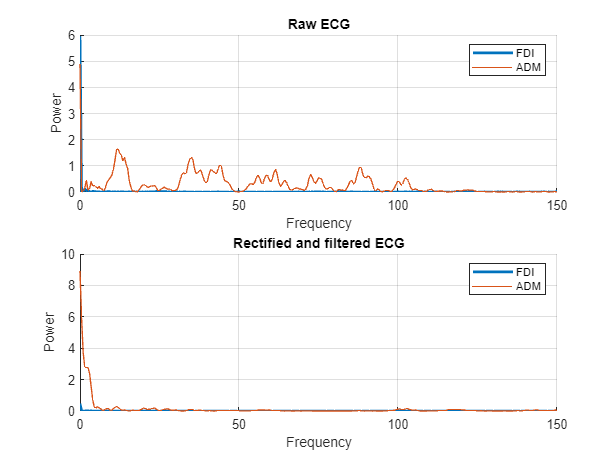

figure()
subplot(2,1,1)
hold on
plot(f,power(:,1,2),'LineWidth',2)
plot(f, power(:,2,2))
hold off
xlabel('Frequency')
ylabel('Power')
xlim([0,150])
legend('FDI','ADM')
title('Raw ECG')
grid("on")

subplot(2,1,2)
hold on
plot(f,power_f(:,1,2),'LineWidth',2)
plot(f, power_f(:,2,2))
hold off
xlabel('Frequency')
ylabel('Power')
xlim([0,150])
legend('FDI','ADM')
title('Rectified and filtered ECG')
grid("on")

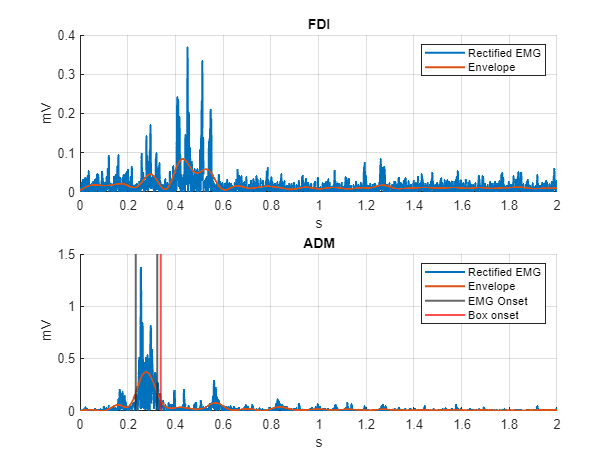

%type 2
figure()

for i = 1:length(values(1,1:2,196)) % 6 channels: 3 to 6 are noise
    subplot(length(rectified_signal(1,1:2,1)),1,i)
    hold on
    plot(t, rectified_signal(:,i,196), t, enveloped_signal(:,i,196), 'LineWidth', 1.5)
    if onset_t(196,i) ~= -1
        xline(onset_t(196,i),'LineWidth',1.5)
        xline(end_signal_t(196,i),'LineWidth',1.5)
        if onset_t(196,3) ~= -1
            xline(onset_t(196,3),'LineWidth',1.5,'Color','r')
            legend('Rectified EMG', 'Envelope', 'EMG Onset', '', 'Box onset')
        else
            legend('Rectified EMG', 'Envelope', '', '')
        end
    else
        legend('Rectified EMG', 'Envelope', '', '')
    end
    hold off
    title(channels(i).title)
    xlabel(x_units)
    ylabel(channels(i).units)
    
    grid("on")
end 

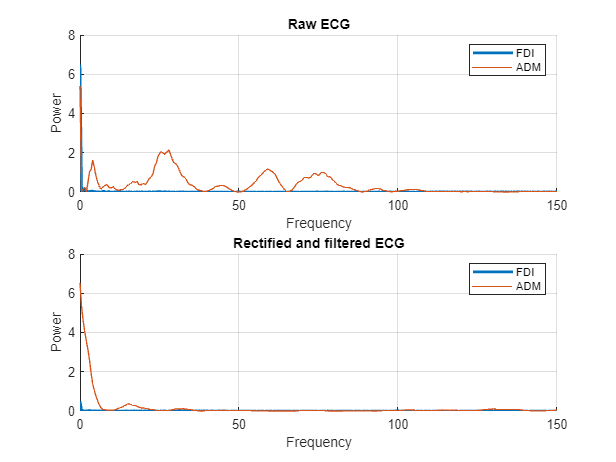


figure()
subplot(2,1,1)
hold on
plot(f,power(:,1,5),'LineWidth',2)
plot(f, power(:,2,5))
hold off
xlabel('Frequency')
ylabel('Power')
xlim([0,150])
legend('FDI','ADM')
title('Raw ECG')
grid("on")

subplot(2,1,2)
hold on
plot(f,power_f(:,1,5),'LineWidth',2)
plot(f, power_f(:,2,5))
hold off
xlabel('Frequency')
ylabel('Power')
xlim([0,150])
legend('FDI','ADM')
title('Rectified and filtered ECG')
grid("on")

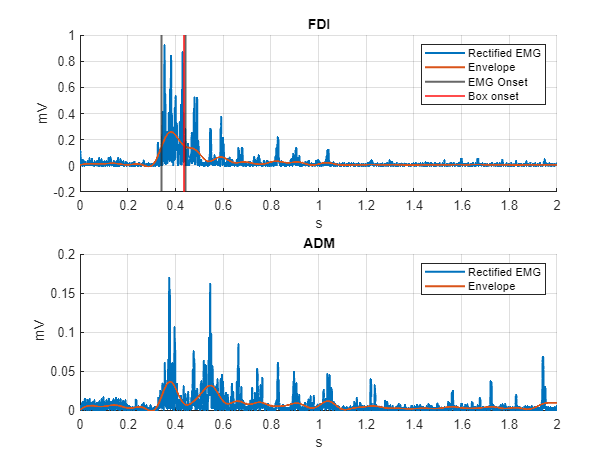

% type 3

figure()
for i = 1:length(values(1,1:2,3)) % 6 channels: 3 to 6 are noise
    subplot(length(rectified_signal(1,1:2,1)),1,i)
    hold on
    plot(t, rectified_signal(:,i,3), t, enveloped_signal(:,i,3), 'LineWidth', 1.5)
    if onset_t(3,i) ~= -1
        xline(onset_t(3,i),'LineWidth',1.5)
        xline(end_signal_t(3,i),'LineWidth',1.5)
        if onset_t(3,3) ~= -1
            xline(onset_t(3,3),'LineWidth',1.5,'Color','r')
            legend('Rectified EMG', 'Envelope', 'EMG Onset', '', 'Box onset')
        else
            legend('Rectified EMG', 'Envelope', '', '')
        end
    else
        legend('Rectified EMG', 'Envelope', '', '')
    end
    hold off
    title(channels(i).title)
    xlabel(x_units)
    ylabel(channels(i).units)
    
    grid("on")
end 

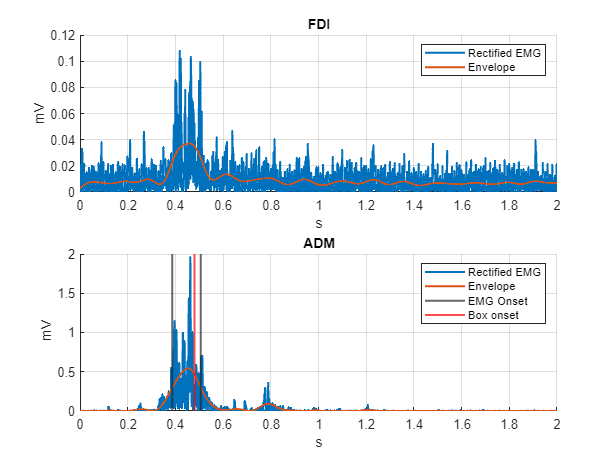

figure()
for i = 1:length(values(1,1:2,7)) % 6 channels: 3 to 6 are noise
    subplot(length(rectified_signal(1,1:2,1)),1,i)
    hold on
    plot(t, rectified_signal(:,i,7), t, enveloped_signal(:,i,7), 'LineWidth', 1.5)
    if onset_t(7,i) ~= -1
        xline(onset_t(7,i),'LineWidth',1.5)
        xline(end_signal_t(7,i),'LineWidth',1.5)
        if onset_t(7,3) ~= -1
            xline(onset_t(7,3),'LineWidth',1.5,'Color','r')
            legend('Rectified EMG', 'Envelope', 'EMG Onset', '', 'Box onset')
        else
            legend('Rectified EMG', 'Envelope', '', '')
        end
    else
        legend('Rectified EMG', 'Envelope', '', '')
    end
    hold off
    title(channels(i).title)
    xlabel(x_units)
    ylabel(channels(i).units)
    
    grid("on")
end 

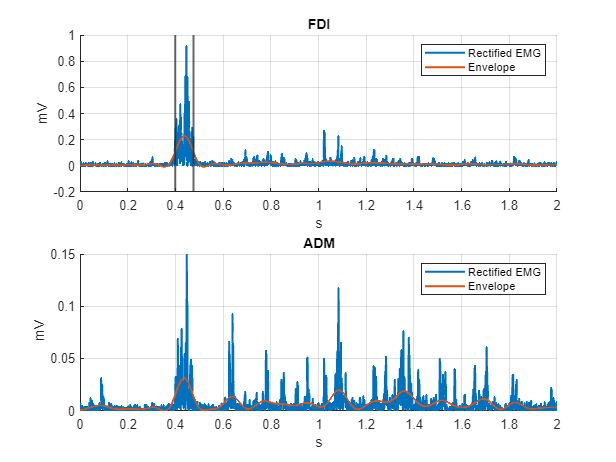

% 99 case
figure()

for i = 1:length(values(1,1:2,9)) % 6 channels: 3 to 6 are noise
    subplot(length(rectified_signal(1,1:2,1)),1,i)
    hold on
    plot(t, rectified_signal(:,i,9), t, enveloped_signal(:,i,9), 'LineWidth', 1.5)
    if onset_t(9,i) ~= -1
        xline(onset_t(9,i),'LineWidth',1.5)
        xline(end_signal_t(9,i),'LineWidth',1.5)
        if onset_t(9,3) ~= -1
            xline(onset_t(9,3),'LineWidth',1.5,'Color','r')
            legend('Rectified EMG', 'Envelope', 'EMG Onset', '', 'Box onset')
        else
            legend('Rectified EMG', 'Envelope', '', '')
        end
    else
        legend('Rectified EMG', 'Envelope', '', '')
    end
    hold off
    title(channels(i).title)
    xlabel(x_units)
    ylabel(channels(i).units)
    
    grid("on")
end 

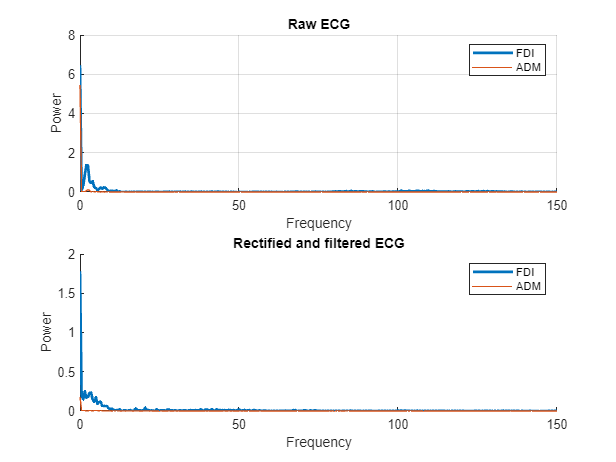

figure()
subplot(2,1,1)
hold on
plot(f,power(:,1,9),'LineWidth',2)
plot(f, power(:,2,9))
hold off
xlabel('Frequency')
ylabel('Power')
xlim([0,150])
legend('FDI','ADM')
title('Raw ECG')
grid("on")

subplot(2,1,2)
hold on
plot(f,power_f(:,1,9),'LineWidth',2)
plot(f, power_f(:,2,9))
hold off
xlabel('Frequency')
ylabel('Power')
xlim([0,150])
legend('FDI','ADM')
title('Rectified and filtered ECG')

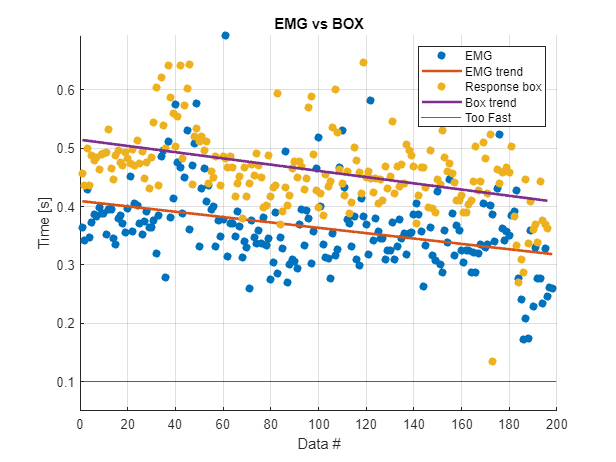

% Reaction time comparison
onset_emg = onset_t(:,1);
onset_box = onset_t(:,3);

indexes = find(onset_emg == -1);
onset_emg(indexes) = onset_t(indexes,2);
onset_emg = onset_emg(onset_emg ~= -1 & onset_emg > low_threshold);
onset_box = onset_box(onset_box ~= -1 & onset_box > low_threshold);

figure()

x_emg = linspace(1,length(onset_emg),length(onset_emg));
x_box = linspace(1,length(onset_box),length(onset_box));

p_emg = polyfit(x_emg, onset_emg, 1);
fit_emg = polyval(p_emg, x_emg);

p_box = polyfit(x_box, onset_box, 1);
fit_box = polyval(p_box, x_box);

hold on
scatter(x_emg, onset_emg, 'filled')
plot(fit_emg, 'LineWidth', 2)
scatter(x_box, onset_box, 'filled')
plot(fit_box, 'LineWidth', 2)
yline(0.1)
ylim([0.05,max(onset_emg)])
hold off
legend('EMG', 'EMG trend', 'Response box', 'Box trend', 'Too Fast')
xlabel("Data #")
ylabel("Time [s]")
title("EMG vs BOX")
grid('on')

% TODO: batch statistic
% TODO: emg for vibration, ps for finger. reaction time?
tests = {t1_index; t2_index; t3_index; t4_index};

for i = 1:length(tests(:,1))
    temp = cell2mat(tests(i));
    disp("Test type: " + i)
    disp("---------------------------------")
    disp("Max: " + max(onset_emg(temp))) % not working
    disp("Min: " + min(onset_emg(temp))) % TODO: get indexes of filtered ones
    disp("Mean: " + mean(onset_emg(temp)))
    disp("Median: " + median(onset_emg(temp)))
    disp("Standard deviation: " + std(onset_emg(temp)))
    disp("---------------------------------")
end

Test type: 1


---------------------------------


Max: 0.57564


Min: 0.24106


Mean: 0.35819


Median: 0.34334


Standard deviation: 0.079512


---------------------------------


Test type: 2


---------------------------------


Max: 0.51063


Min: 0.20905


Mean: 0.36503


Median: 0.36959


Standard deviation: 0.064424


---------------------------------


Test type: 3


---------------------------------


Max: 0.49462


Min: 0.17254


Mean: 0.33816


Median: 0.33858


Standard deviation: 0.054966


---------------------------------


Test type: 4


---------------------------------


Max: 0.69367


Min: 0.27607


Mean: 0.39298


Median: 0.38385


Standard deviation: 0.072255


---------------------------------
